clear; clc;
load('..\ECG_with_noise.mat');

Butterworth Low pass 

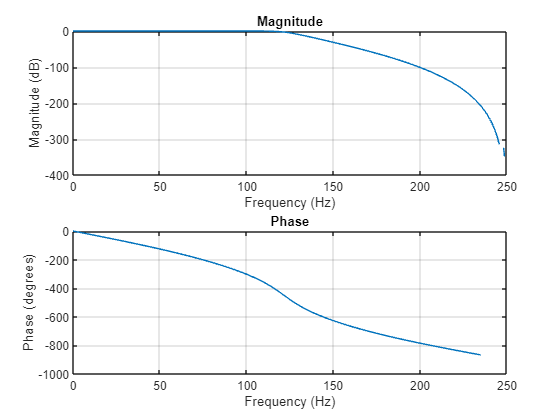

fs = 500;  
T = 1/fs; 

fc_low = 121.582;

% order_low = 61;
order_low = 10;

[b_low,a_low] = butter(order_low,2*fc_low/fs,"low");

freqz(b_low,a_low,[],fs)

fvtool(b_low,a_low,'Fs',fs);

Butterworth High pass

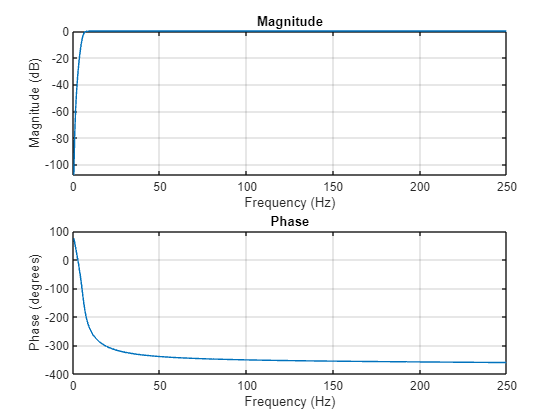

fc_high = 5.85;
order_high = 5;

[b_high,a_high] = butter(order_high,2*fc_high/fs,"high");

freqz(b_high,a_high,[],fs)

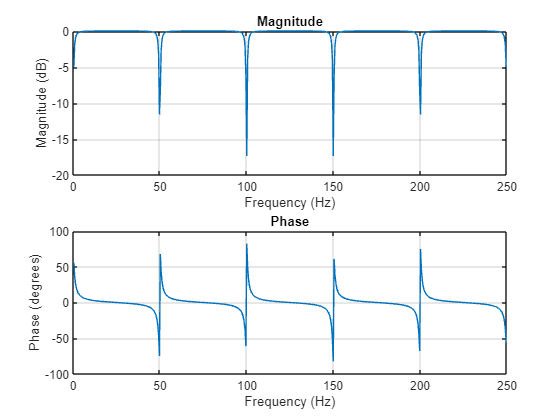

fo_comb = 50;
q = 35;
bw = (fo_comb/(fs/2))/q;
[b_comb,a_comb] = iircomb(fs/fo_comb,bw,'notch'); % Note type flag 'notch'
freqz(b_comb,a_comb,[],fs);

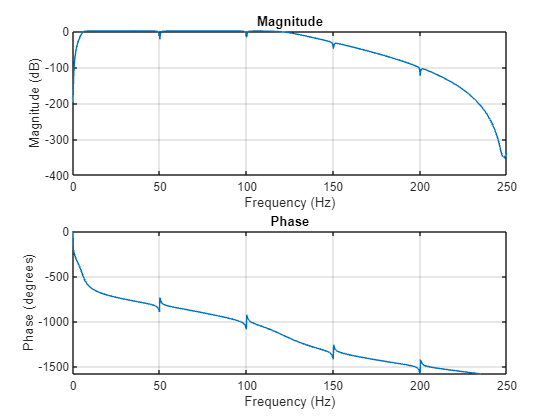

% fvtool(b_comb,a_comb);
combined_numerator = conv(conv(b_low, b_high), b_comb);
combined_denominator = conv(conv(a_low, a_high), a_comb);

freqz(combined_numerator,combined_denominator,1024,fs); 

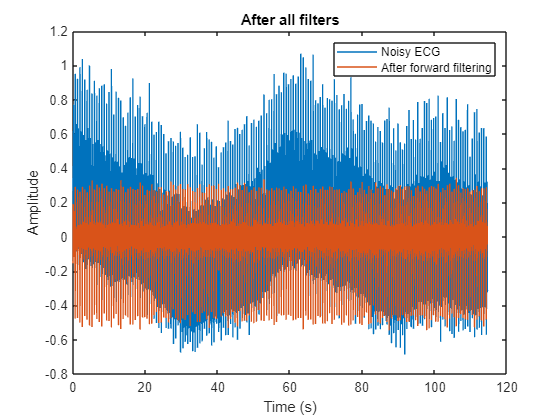

num_points = size(nECG, 2);
time_axis = linspace(0, T * (num_points-1), num_points); 

forward_filtered_signal = filter(combined_numerator,combined_denominator,nECG);
group_delay = round(mean(grpdelay(combined_numerator,combined_denominator)));
forward_filtered_signal(1:group_delay) = [];

figure;
plot(time_axis, nECG);
hold on;
plot(time_axis(1:end-group_delay), forward_filtered_signal);

xlabel('Time (s)');
ylabel('Amplitude');
legend("Noisy ECG","After forward filtering");
title('After all filters');
hold off;

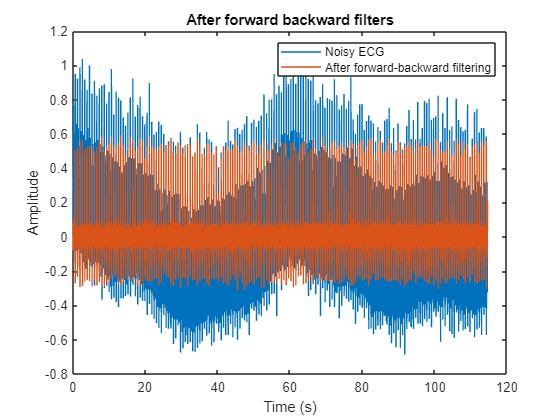

forward_backward_filtered_signal = filtfilt(combined_numerator,combined_denominator,nECG);
% group_delay = 2*round(mean(grpdelay(combined_numerator,combined_denominator)));
% forward_backward_filtered_signal(1:group_delay) = [];

figure;
plot(time_axis, nECG);
hold on;
% plot(time_axis(1:end-group_delay), forward_backward_filtered_signal);
plot(time_axis, forward_backward_filtered_signal);



xlabel('Time (s)');
ylabel('Amplitude');
legend("Noisy ECG","After forward-backward filtering");
title('After forward backward filters');
hold off;

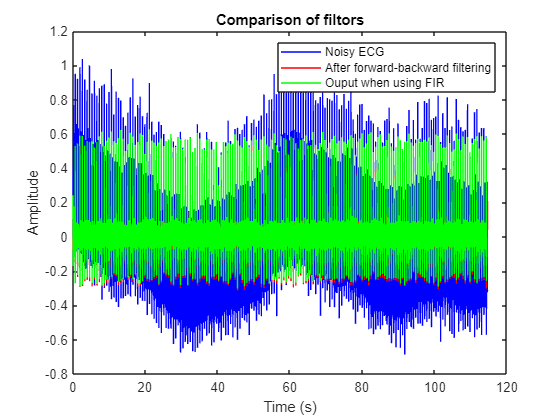

load 'FIR output.mat';
FIR_output = after_comb;

figure;
plot(time_axis, nECG,'b');
hold on;
% plot(time_axis(1:end-group_delay), forward_backward_filtered_signal,'r');
plot(time_axis, forward_backward_filtered_signal,'r');
hold on;
plot(time_axis_FIR_output,FIR_output,'g');
hold off;

xlabel('Time (s)');
ylabel('Amplitude');
legend("Noisy ECG","After forward-backward filtering","Ouput when using FIR");
title('Comparison of filtors');

Initializing Window Designer....

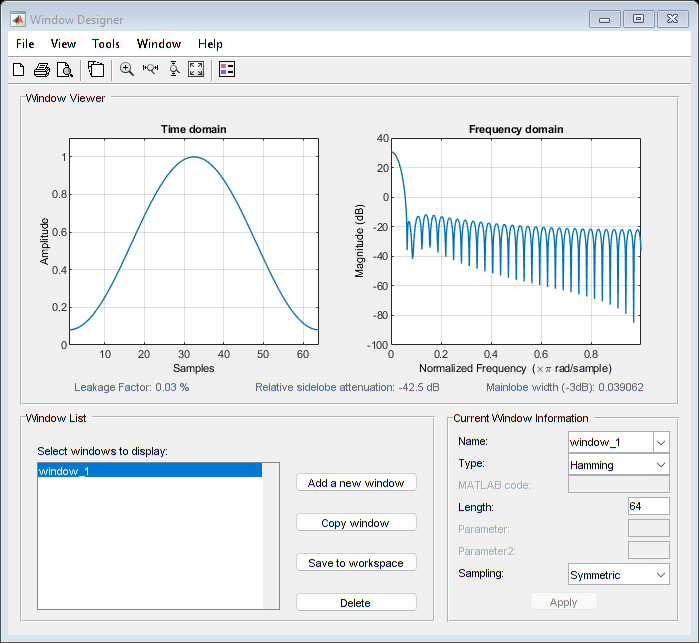

. done. 


[pxx_FIR_output,f_FIR_output] = periodogram(FIR_output,window,length(FIR_output),fs);

Initializing Window Designer....

. done. 


[pxx_forward,f_forward] = periodogram(forward_filtered_signal,window,length(forward_filtered_signal),fs);

[pxx_forward_backward, f_forward_backward] = periodogram(forward_backward_filtered_signal,window,length(forward_backward_filtered_signal),fs);

Initializing Window Designer....

. done. 



figure;
plot(f_FIR_output, 10*log10(pxx_FIR_output),'c'); 
hold on;
plot(f_forward, 10*log10(pxx_forward)); 
hold on;
plot(f_forward_backward, 10*log10(pxx_forward_backward)); 
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
legend('FIR','Forward IIR','Forward-Backward IIR')
title('Power Spectral Density (PSD) comparison');